Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |       44.53% |       70.00% |       0.8503 |       0.9880 |          0.0100 |
|      25 |          50 |       00:00:17 |      100.00% |       97.50% |       0.0442 |       0.0902 |          0.0100 |
|======================================================================================================================|
Training finished: Max epochs completed.


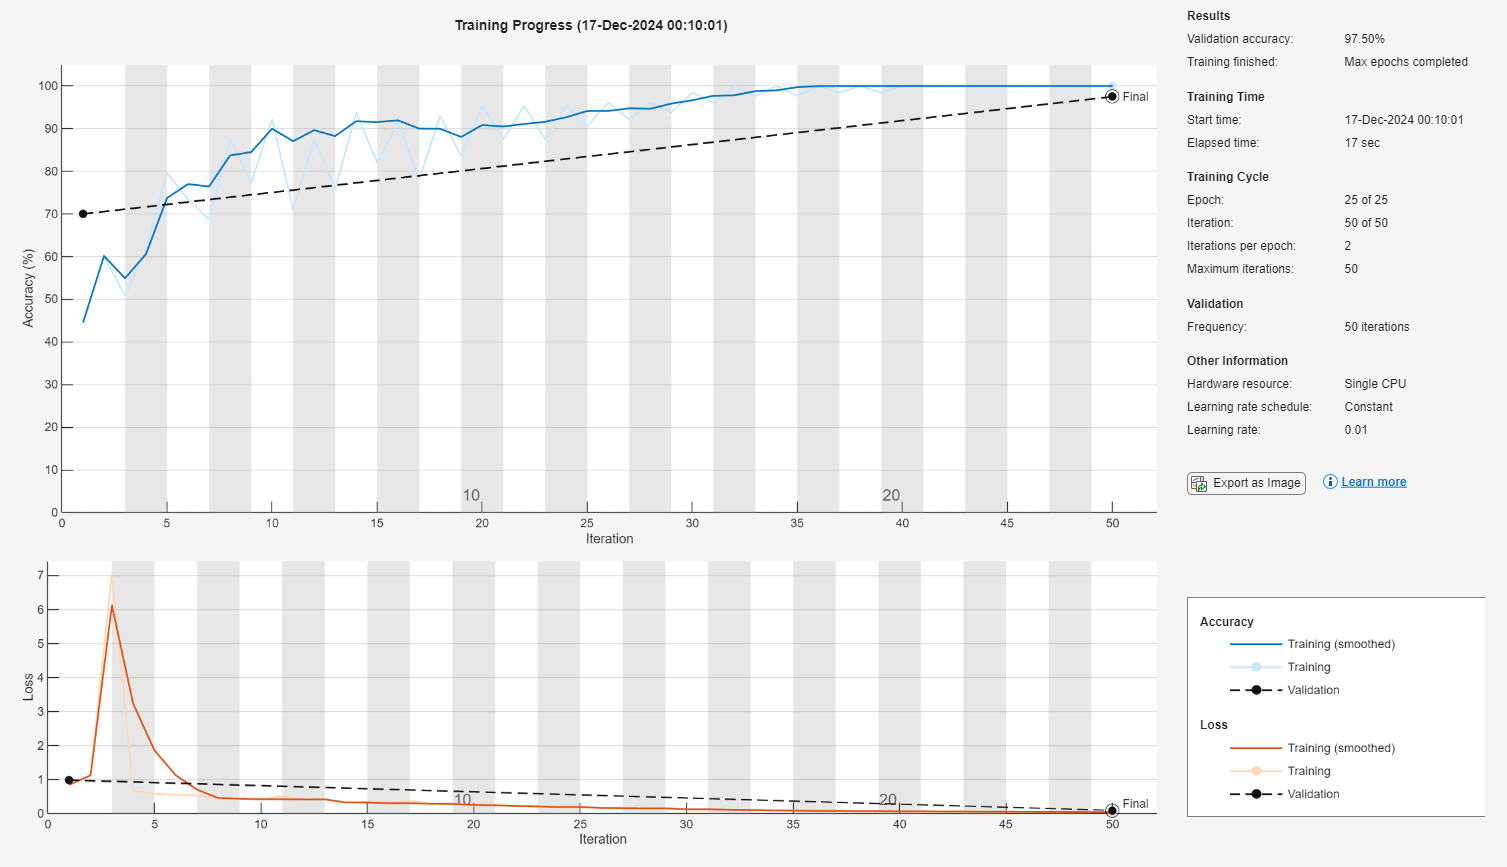

clear;

% Locate the repository directory
projectRoot = fileparts(which("CNN.mlx"));
% Loading the training data
trainingDataFolder = fullfile(projectRoot, "data", "training");
trainingData = zeros(500, 6, 1, 320);
trainingDataLabel = zeros(1, 320);
for i = 1:320
    % Construct full file path to each .mat file
    filePath = fullfile(trainingDataFolder, sprintf("%d.mat", i));
    
    % Load the .mat file
    matFile = load(filePath);
    
    % Store the data into the 3D array
    trainingData(:, :, 1, i) = matFile.X;
    trainingDataLabel(1,i) = matFile.label;
end
trainingDataLabel = categorical(trainingDataLabel);  % Convert training labels

% Loading the validation data
validationDataFolder = fullfile(projectRoot, "data", "validation");
validationData = zeros(500, 6, 1, 80);
validationDataLabel = zeros(1,80);
for i = 1:80
    % Construct full file path to each .mat file
    filePath = fullfile(validationDataFolder, sprintf("%d.mat", i));
    
    % Load the .mat file
    matFile = load(filePath);
    
    % Store the data into the 3D array
    validationData(:, :, 1, i) = matFile.X;
    validationDataLabel(1,i) = matFile.label;
end
validationDataLabel = categorical(validationDataLabel);  % Convert validation labels

% Clean up the workspace
clear matFile filePath i trainingDataFolder validationDataFolder

% Building the CNN layers
CNNsetting = [
    % Input layer
    imageInputLayer([500 6 1], "Name", "input");

    % Convolution layer 1
    convolution2dLayer([5 1], 16, "Padding", "same", "Name", "1st Convolution", "WeightsInitializer", "he");
    leakyReluLayer(0.1,"Name","Leaky ReLU 1");

    % Convolution layer 2
    convolution2dLayer([5 1], 32, "Padding", "same", "Name", "2nd Convolution", "WeightsInitializer", "he");
    leakyReluLayer(0.1,"Name","Leaky ReLU 2");

    % Pooling layer
    averagePooling2dLayer([2 1], "Stride", [2 1], "Name", "Pooling");

    % Flatten Layer
    flattenLayer("Name", "Flatten");
    
    % Fully connected layer 1
    fullyConnectedLayer(64, "Name", "Fully Connected Layer 1", "WeightsInitializer", "he");
    leakyReluLayer(0.01, "Name", "Leaky ReLU 3");
    
    % Fully connected layer 2 and output
    fullyConnectedLayer(2, "Name", "Fully Connected Layer 2");
    softmaxLayer("Name", "Softmax")
    classificationLayer("Name", "Output");
];

% Building the testing setting
trainingSetting = trainingOptions("sgdm", "InitialLearnRate", 0.01, "Momentum", 0 , "MaxEpochs", 25, "ValidationData", {validationData,validationDataLabel}, "Plots", "training-progress");

% Passing in the training and validation data
training = trainNetwork(trainingData, trainingDataLabel, CNNsetting, trainingSetting);

analyzeNetwork(training)
% Loading in the testing data
testingDataFolder = fullfile(projectRoot, "data", "testing");
file = dir(fullfile(testingDataFolder, "*.mat"));
testingData = zeros(500, 6, 1, 30);
testingDataLabel = zeros(1,30);
for i = 1:30
    % Construct full file path to each .mat file
    filePath = fullfile(testingDataFolder, file(i).name);

    matFile = load(filePath);

    testingData(:, :, 1, i) = matFile.X;
    testingDataLabel(1,i) = matFile.label;

end
testingDataLabel = categorical(testingDataLabel);

% Clean up the workspace
clear matFile filePath file i testingDataFolder

predictedLabel = classify(training,testingData);
accuracy = sum(predictedLabel == testingDataLabel') / numel(testingDataLabel) * 100;
disp(['Testing Accuracy: ', num2str(accuracy), '%']);

Testing Accuracy: 86.6667%


% Confusion Matrix
confusionMatrix = confusionmat(testingDataLabel, predictedLabel);

% Extract values from confusion matrix
truePositive = confusionMatrix(2, 2);       % Correctly predicted '1'
falsePositive = confusionMatrix(1, 2);      % Predicted '1', but actual '0'
falseNegative = confusionMatrix(2, 1);      % Predicted '0', but actual '1'
trueNegative = confusionMatrix(1, 1);       % Correctly predicted '0'

% Calculate and display precision, recall, and F1-Score
precision = truePositive / (truePositive + falsePositive);
recall = truePositive / (truePositive + falseNegative);
f1Score = 2 * (precision * recall) / (precision + recall);

fprintf('Precision: %.2f%%\n', precision * 100);

Precision: 83.33%


fprintf('Recall: %.2f%%\n', recall * 100);

Recall: 93.75%


fprintf('F1-Score: %.2f%%\n', f1Score * 100);

F1-Score: 88.24%
